%

% opgave 1.3 


% denne kode er devist elle fuldstændigt givet sol løsning til E23 Exam i
% løsningsforslaget!! 
W = -pi:0.001:pi;
mag = 6+2*cos(2*W)+4*cos(W)

mag =     4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    3.9999    3.9999    3.9999    3.9998    3.9998    3.9998    3.9997    3.9997    3.9996    3.9996    3.9995    3.9994    3.9994    3.9993    3.9992    3.9991    3.9990    3.9989    3.9988    3.9988    3.9986    3.9985    3.9984    3.9983    3.9982    3.9981    3.9980    3.9978    3.9977    3.9976    3.9974    3.9973    3.9971    3.9970    3.9968    3.9966    3.9965    3.9963    3.9961    3.9960    3.9958    3.9956    3.9954    3.9952


phase = -2*W % denne er den fase som er i arg(H(w)) = exp(-2Iw) i dette tilfælde, man fjerner dog I 

phase =     6.2832    6.2812    6.2792    6.2772    6.2752    6.2732    6.2712    6.2692    6.2672    6.2652    6.2632    6.2612    6.2592    6.2572    6.2552    6.2532    6.2512    6.2492    6.2472    6.2452    6.2432    6.2412    6.2392    6.2372    6.2352    6.2332    6.2312    6.2292    6.2272    6.2252    6.2232    6.2212    6.2192    6.2172    6.2152    6.2132    6.2112    6.2092    6.2072    6.2052    6.2032    6.2012    6.1992    6.1972    6.1952    6.1932    6.1912    6.1892    6.1872    6.1852


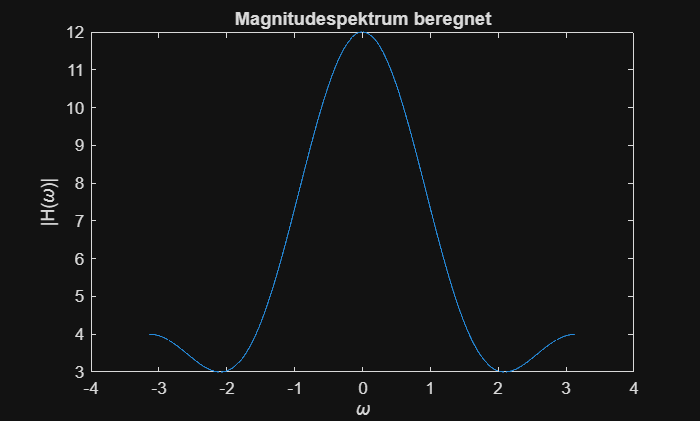

f1 = figure;
plot(W, mag);
title('Magnitudespektrum beregnet')
xlabel('\omega')
ylabel('|H({\omega})|')

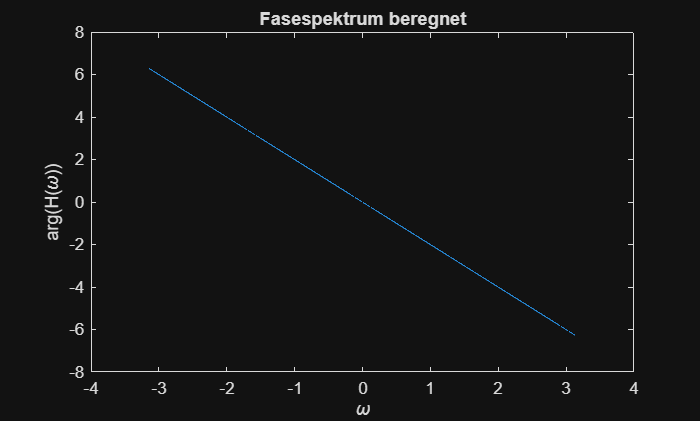

f2 = figure;
plot(W, phase);
title('Fasespektrum beregnet')
xlabel('\omega')
ylabel('arg(H({\omega}))') 

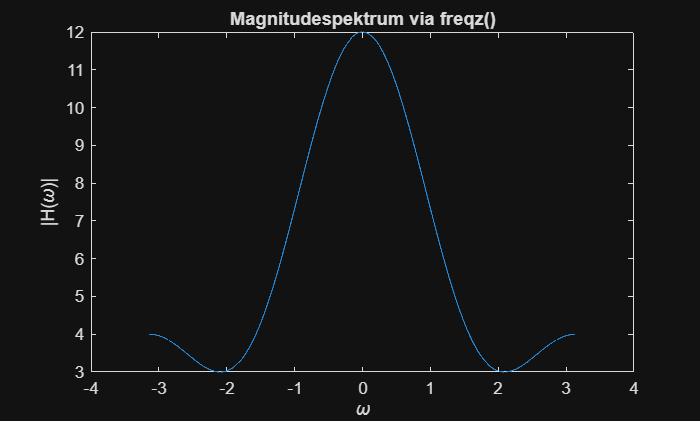


% Definer A,B koefficenter og omega-interval
A = [1];
B = [1 2 6 2 1]; %% HUSK AT ÆNDRE KOEFFICENTER
H_d = freqz(B,A,W);
mag_d = abs(H_d);
phase_d = angle(H_d);
f3 = figure;
plot(W,mag_d);
title('Magnitudespektrum via freqz()')
xlabel('\omega')
ylabel('|H({\omega})|')

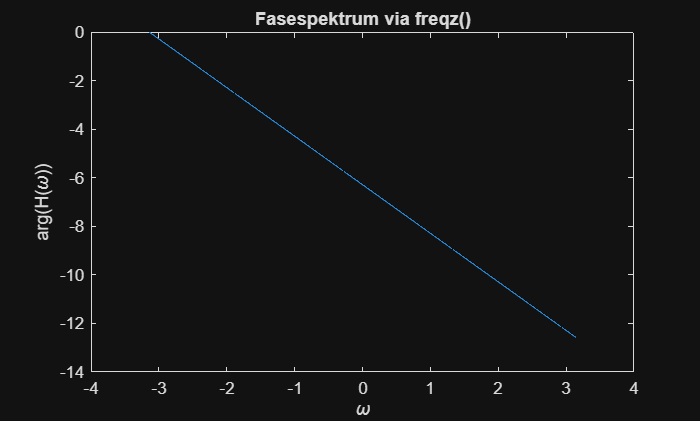

f4 = figure;
plot(W,unwrap(phase_d));
title('Fasespektrum via freqz()')
xlabel('\omega')
ylabel('arg(H({\omega}))')

Opgave 2.1 

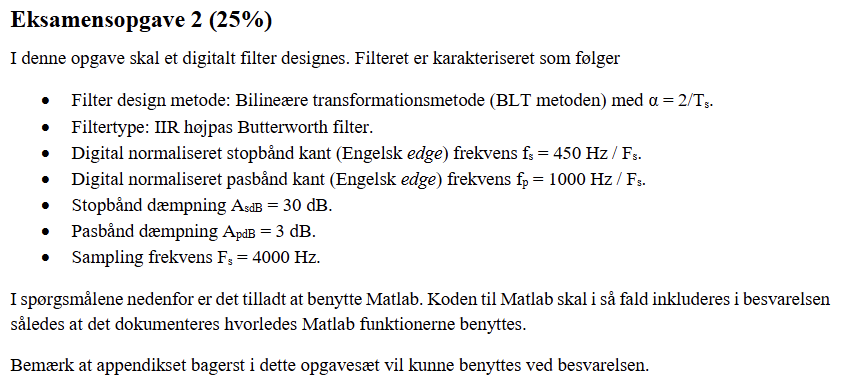

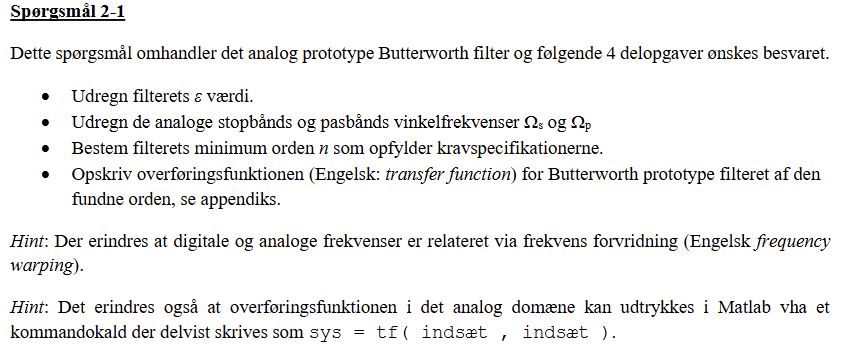

clear
% IIR højpass Butterworth filter

% opgivede variable: 

Fs = 4000; % sample freq
Ts= 1/Fs; % always and always
fstop = 450/Fs; %norm stop freq
fpass = 1000/Fs; %norm pass freq
AsdB = 30; %stopbånd dæmpning
ApdB = 3; %passbånd dæmpning
alfa = 2/Ts; 


%   a) 

%vi udregner epsilon

epsilon_i_anden = 10^(0.1*ApdB)-1;

epsilon = sqrt(epsilon_i_anden) 

epsilon = 0.9976


%epsilon = 1.4125    -------resultat---------


%   b) 

% for at kunne udregne de analoge frekvenser følger vi denne metode: 


wstop = fstop*2*pi;

wpass = fpass*2*pi;


Ostop = (2/Ts)*tan(wstop/2)  % analog norm angulær stop freq

Ostop = 2.9514e+03


Opass = (2/Ts)*tan(wpass/2) % analog norm angulær pass freq

Opass = 8.0000e+03


% Ostop = 2.5994e+03  ----------------resultat---------------

% Ostop = 2.5994e+03  ----------------resultat---------------


%   c) 

% for at beregne ordenen skal vi bruge følgende formel hvor vi skal finde
% "new"s først 

 news = Opass/Ostop

news = 2.7106


%vi finder den minimale orden af et chebyshev Type 1 filter vi kan bruge 


n_test = (log10( (  (10^(0.1*AsdB))-1 )    / ((epsilon_i_anden) )))  /( 2*log10(news))

n_test = 3.4655


% nedenfor ser vi at vi at ordenen skal være:

% n_test = 3.4655     -----resultat------
% vi runder derfor op: 

% n= 4             ----------resultat---------


%   d) 

% vi slår koefficenterne op i appendix: 

b = [1];
a = [1, 2.6131, 3.4142, 2.6131, 1];

H_proto = tf(b,a) 


H_proto =
 
                      1
  -----------------------------------------
  s^4 + 2.613 s^3 + 3.414 s^2 + 2.613 s + 1
 
Continuous-time transfer function.



%============================================================% 
%                                 1                          %
%  H_proto =   -----------------------------------------     %
%              s^4 + 2.613 s^3 + 3.414 s^2 + 2.613 s + 1     %
%============================================================%



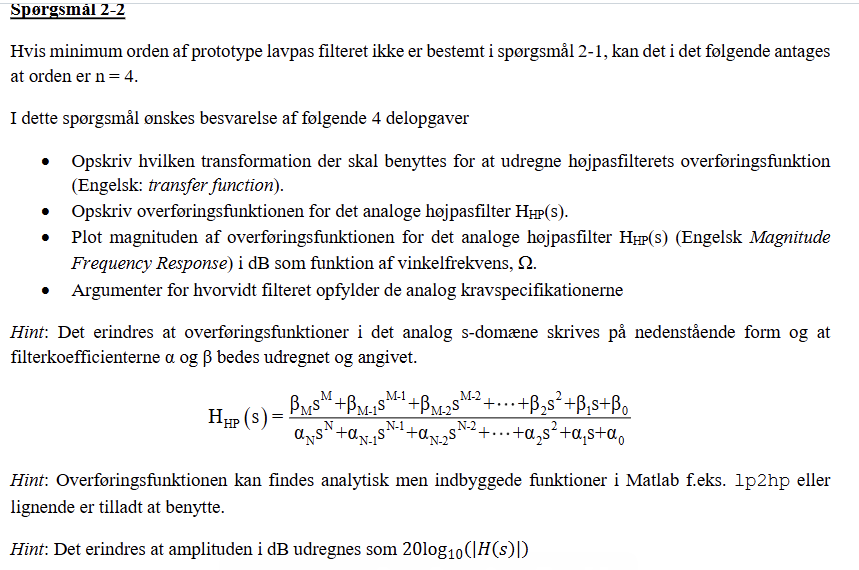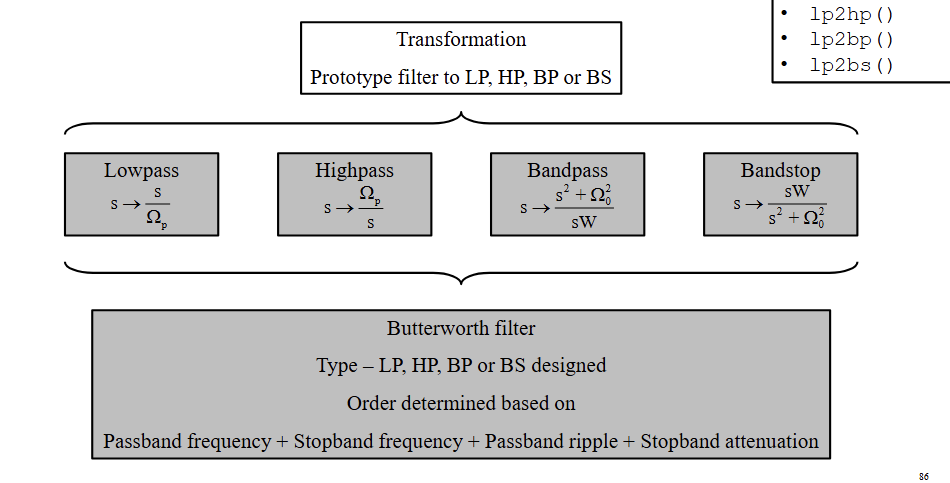

%  2.2 

%for et højpas skal vi bruge transformationen: 
 
   %a) 
%for et højpas skal vi bruge transformationen: 

%    s-> Opass/s     -- hvor Opass er den  normaliserede analoge pasbånd frekvens

%    b)    

% vi finder overføringsfunktionen: 

[num, den] = lp2hp(b, a, Opass)

num =     1.0000    0.0000    0.0000    0.0004         0


den = 1.0e+15 *

    0.0000    0.0000    0.0000    0.0013    4.0960



HHP = tf(num,den)


HHP =
 
     s^4 + 5.773e-12 s^3 + 4.719e-09 s^2 + 0.0003625 s
  --------------------------------------------------------
  s^4 + 2.09e04 s^3 + 2.185e08 s^2 + 1.338e12 s + 4.096e15
 
Continuous-time transfer function.


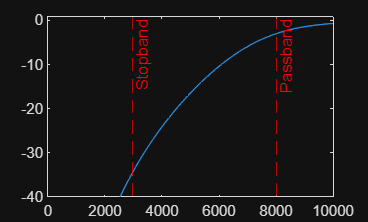



%===================================================================%
%             s^4 + 5.773e-12 s^3 + 4.719e-09 s^2 + 0.0003625 s     %
% HHP    = -------------------------------------------------------- %
%          s^4 + 2.09e04 s^3 + 2.185e08 s^2 + 1.338e12 s + 4.096e15 % 
%===================================================================% 


[H_ana_H, anafreq] = freqs(num,den,1024);

plot(anafreq, 20*log10(abs(H_ana_H)))
xline(Ostop,'--r', "Stopband") % indsætter en linje for stopbåndsfrek 
xline(Opass,'--r', "Passband") % indsætter en linje for passbåndsfrek 

xlim([0,10000])
ylim([-40,1])


[~,idx]=min(abs(anafreq - Ostop));
stop_freq=20*log10(abs(H_ana_H(idx)))

stop_freq = -34.4621

[~,idx]=min(abs(anafreq - Ostop));
pass_freq=20*log10(abs(H_ana_H(idx)))

pass_freq = -34.4621


% det er ret tydeligt at se at vi opfylder kravene   -----resultat-----

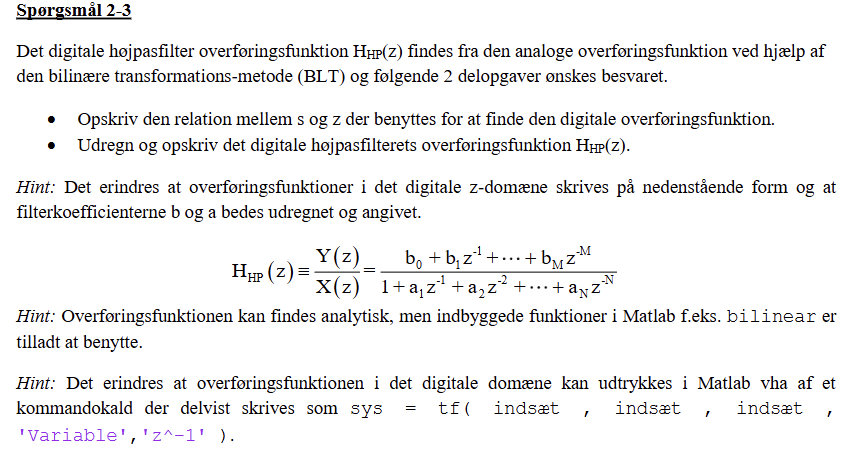

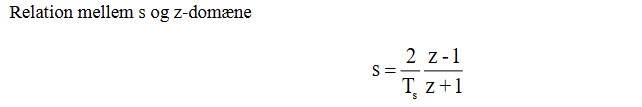

% Opgave 2.3

%   a) -------------------------

% relationen mellem s og z: 

%   s= (2/Ts)*((z-1)/(z+1)      -----resultat-----

%   b) -----------------------
% vi udregner således: 

[numdig,dendig] = bilinear(num,den,Fs)  % vi får digitale nævner og tæller med bilinear transform

numdig =     0.0940   -0.3759    0.5639   -0.3759    0.0940


dendig =     1.0000    0.0000    0.4860    0.0000    0.0177



% vi opskriver den digitale overføringsfunktion:
HHP_dig = tf(numdig,dendig,Ts,'Variable','z^-1')


HHP_dig =
 
  0.09398 - 0.3759 z^-1 + 0.5639 z^-2 - 0.3759 z^-3 + 0.09398 z^-4
  ----------------------------------------------------------------
  1 + 3.903e-16 z^-1 + 0.486 z^-2 + 3.662e-16 z^-3 + 0.01767 z^-4
 
Sample time: 0.00025 seconds
Discrete-time transfer function.


HHHPdig = filt(numdig,dendig);% det her virker også 
% vi får : 
%----------------------------------resultat------------------------
%===============================================================================%
%            0.09398 - 0.3759 z^-1 + 0.5639 z^-2 - 0.3759 z^-3 + 0.09398z^-4    %
% HHP_dig = ----------------------------------------------------------------    %
%           1 + 3.903e-16 z^-1 + 0.486 z^-2 + 3.662e-16 z^-3 + 0.01767 z^-4     %
%===============================================================================%


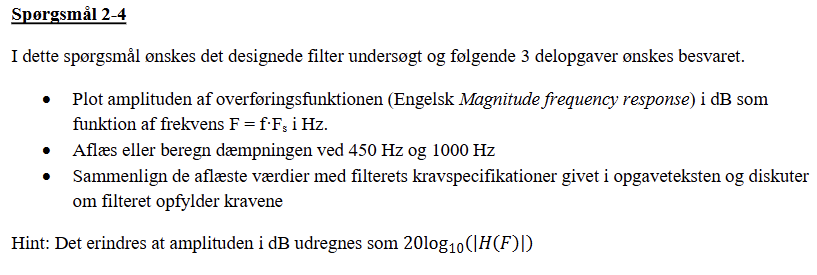

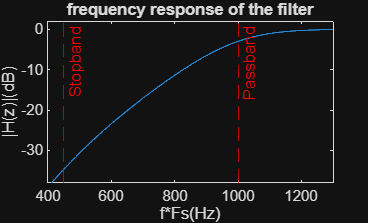

% opgave 2.4 

[HHP_dig, freqdig] = freqz(numdig,dendig,1024,Fs); %dig freq skaleret op til Fs 

plot(freqdig,20*log10(abs(HHP_dig)))
xline(fstop*Fs,'--r', "Stopband") % indsætter en linje for stopbåndsfrek 
xline(fpass*Fs,'--r', "Passband") % indsætter en linje for passbåndsfrek 

xlim([400, 1300])
ylim([-38,2])

xlabel('f*Fs(Hz)')
ylabel(['|H(z)|(dB)'])
title('frequency response of the filter')
hold off

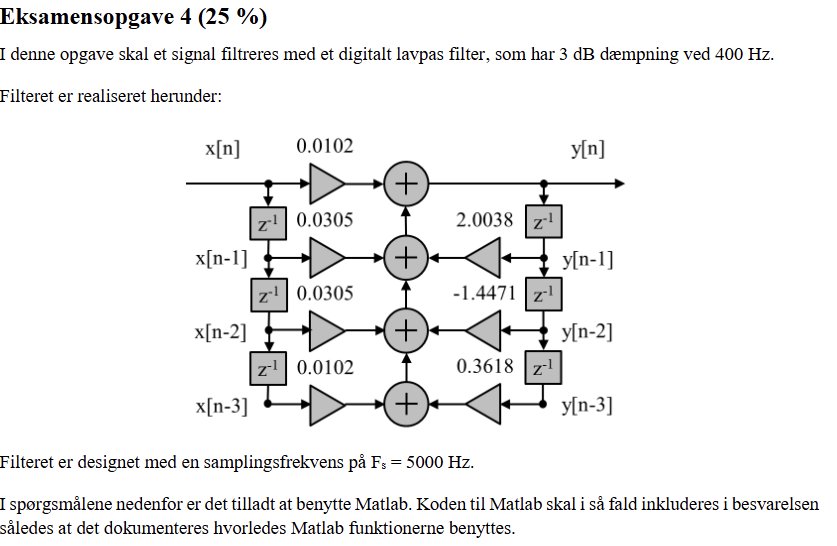

clear
%KEYWORD : FORTEGN SF KOEFFICENTERNE ER ALTID FEEJLEN!!!!!


ApdB = 3;  %pasbånds dæmpning
Fpass = 400; % passbånds freq 
Fs= 5000; 
Ts = 1/Fs

Ts = 2.0000e-04



% husk her at altid tilføje a0 = 1 (den kommer fra y[n] = +1 som første koeff)
% husk også at sætte et minus foran a koefficenterne
% og det der er lidt underligt her er at b koefficenterne er på x siden men
% det er dem som skal være overstregen i overføringsfunktionen

b = [0.0102, 0.0305, 0.0305, 0.0102]; %b koeef
%her husk negativt fortegn!!! 
a = [1, -2.0038, 1.4471, -0.3618];
%her husk Ts ellers får du H(s) i stedet 

Hz = tf(b,a,Ts,'Variable','z^-1') % indskriver koefficenter i H(z)


Hz =
 
  0.0102 + 0.0305 z^-1 + 0.0305 z^-2 + 0.0102 z^-3
  ------------------------------------------------
     1 - 2.004 z^-1 + 1.447 z^-2 - 0.3618 z^-3
 
Sample time: 0.0002 seconds
Discrete-time transfer function.




%nedenfor ser vi overføringsfunktionen

%===========================================================%
%         0.0102 + 0.0305 z^-1 + 0.0305 z^-2 + 0.0102 z^-3  % 
% H(z) =  ------------------------------------------------  % 
%            1 - 2.004 z^-1 + 1.447 z^-2 - 0.3618 z^-3      %
%===========================================================%



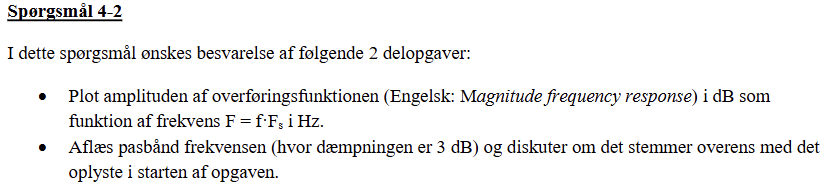

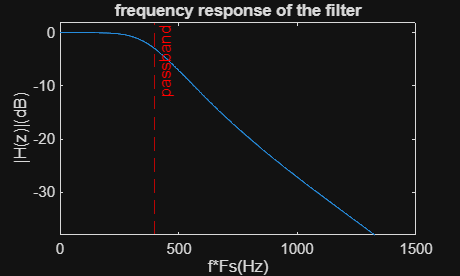

[HLP_dig, freqdig] = freqz(b,a,1024,Fs);

plot(freqdig,20*log10(abs(HLP_dig)))
xline(Fpass,'--r', "passband") % indsætter en linje for pass    båndsfrek 


xlim([0,1500])
ylim([-38,2])

xlabel('f*Fs(Hz)')
ylabel(['|H(z)|(dB)'])
title('frequency response of the filter')
hold off

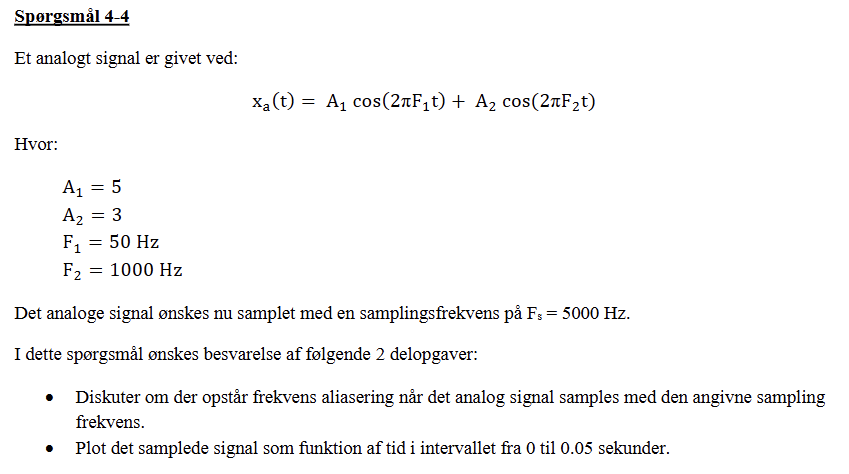


%opgave 4.4 
Fs = 5000; %sampling frekvens, skal dog ikke bruges 
A1 = 5; % konstant 1 
A2 = 3; % konstant 2 
F1 = 50; %første frekvens
F2 = 1000; %anden frekvens
Ts = 1/Fs;

%husk her i tidsaksen at man skal inkrimentere med ret lidt for at få et
%pænt signal men Ts er standard og virker fint i dette tilfælde 
t = 0:Ts:0.05;

xat = A1*cos(2*pi*F1*t) + A2*cos(2*pi*F2*t)

xat =     8.0000    5.9172    2.5335    2.4844    5.7700    7.7553    5.5759    2.0971    1.9545    5.1487    7.0451    4.7796    1.2178    0.9957    4.1142    5.9389    3.6062   -0.0183   -0.2982    2.7677    4.5451    2.1705   -1.4901   -1.8004    1.2410    3.0000    0.6131   -3.0537   -3.3640   -0.3164    1.4549   -0.9136   -4.5559   -4.8358   -1.7521    0.0611   -2.2601   -5.8498   -6.0719   -2.9255   -1.0451   -3.2946   -6.8086   -6.9512   -3.7218   -1.7553   -3.9159   -7.3385   -7.3876   -4.0631


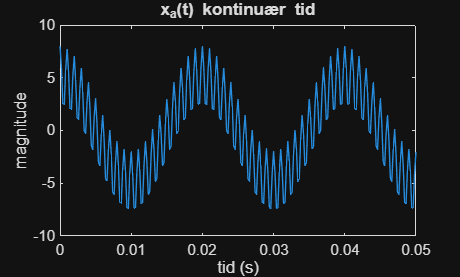


plot(t, xat);
title('x_a(t) kontinuær tid')
xlabel('tid (s)')
ylabel('magnitude')
hold off

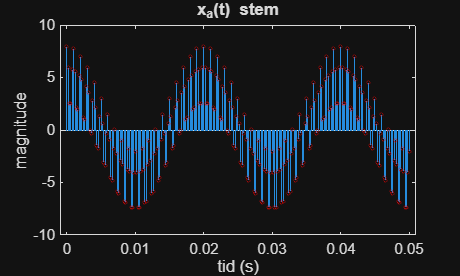


stem(t,xat,'lineWidth',0.2,'MarkerSize',2,'MarkerEdgeColor','red')
title('x_a(t) stem')
xlabel('tid (s)')
ylabel('magnitude')

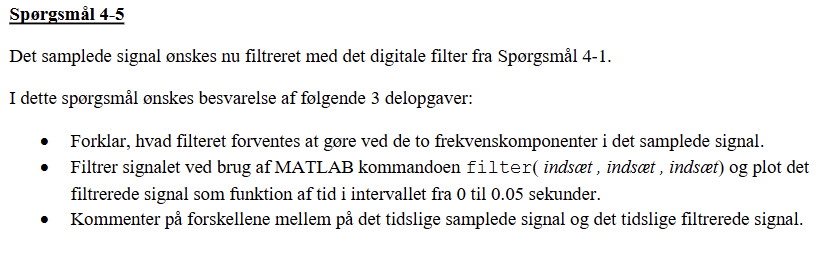

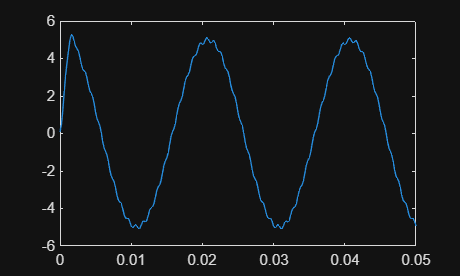

%opgave 4.5


% vi er nød til at antage at b og a koefficenterne er det samme som forrige
% opgave
xt_filtered = filter(b,a,xat);


plot(t,xt_filtered)